## Convertire un immagine di maps

Prende un immagine la converte in bianco e nero per poi salvarla in formato '.mat' e infine si calcola l'occupancy map.

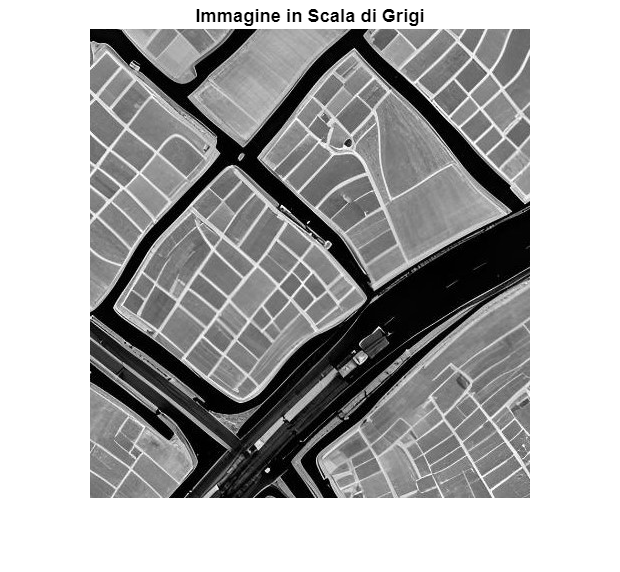

% Carica l'immagine
img = imread('Images\maps_4_2.jpg');

% Converti l'immagine in scala di grigi
grayImg = rgb2gray(img);

% Mostra l'immagine in scala di grigi
figure;
imshow(grayImg);
title('Immagine in Scala di Grigi');

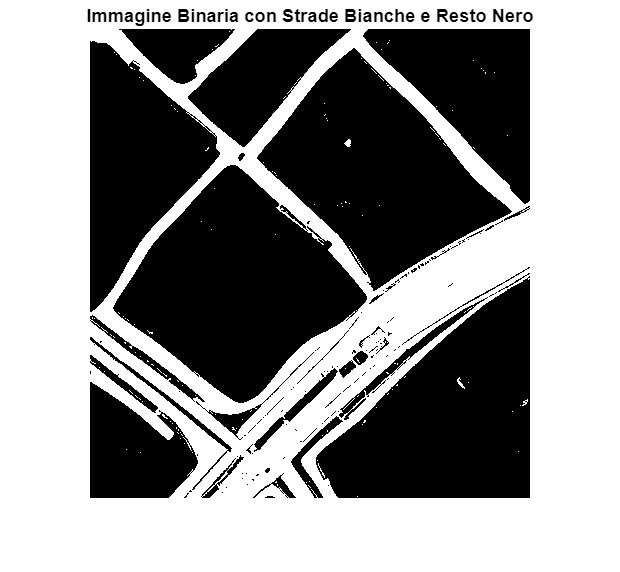


% Applica una soglia per creare un'immagine binaria (bianco e nero)
threshold = graythresh(grayImg); % Usa Otsu's method per determinare la soglia
binaryImg = imbinarize(grayImg, threshold);

% Inverti l'immagine binaria (strade bianche, resto nero)
binaryImg = ~binaryImg;

% Mostra l'immagine binaria
figure;
imshow(binaryImg);
title('Immagine Binaria con Strade Bianche e Resto Nero');

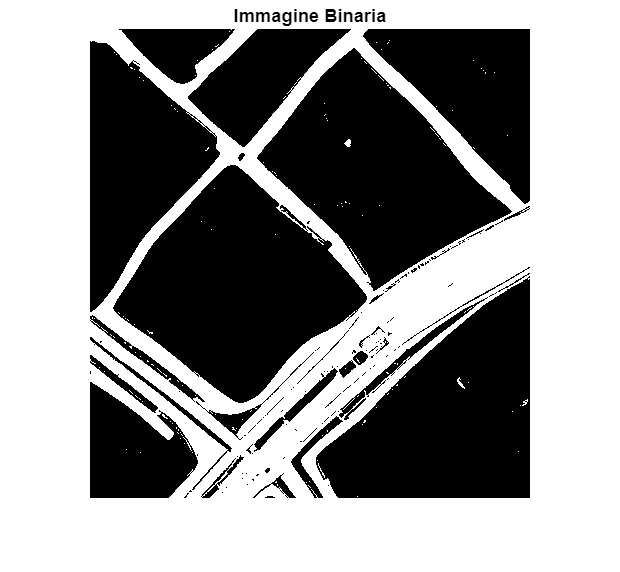

% Salva l'immagine binaria in un file .mat
save('Files_mat\maps_4_2.mat', 'binaryImg');

% Carica l'immagine binaria
% load('maps_4_2.mat');

% Assumendo che l'immagine binaria sia salvata come 'binaryImage'
% Puoi visualizzarla per verificare
figure;
imshow(binaryImg);
title('Immagine Binaria');

### Prende il file mat e mi crea la occupancy map

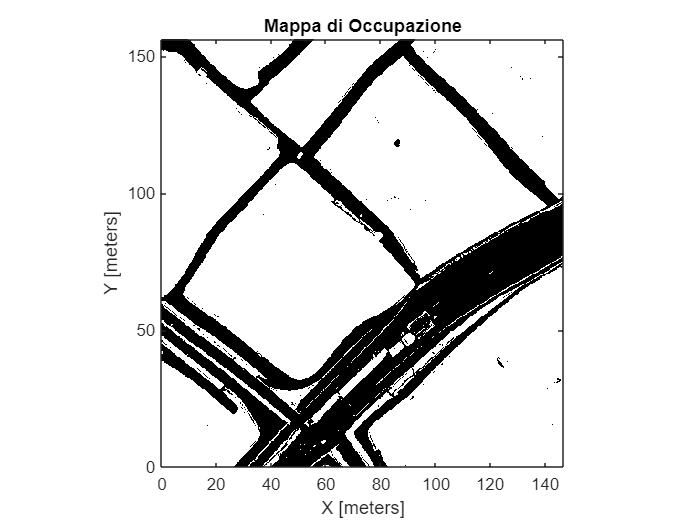

% Imposta la risoluzione della mappa di occupazione
resolution = 3; % puoi regolare la risoluzione come necessario

% Crea la mappa di occupazione
map = binaryOccupancyMap(binaryImg, resolution);

% Visualizza la mappa di occupazione
figure;
show(map);
title('Mappa di Occupazione');

% Salva la mappa di occupazione in un file .mat
save(['Files_mat\occupancyMap_maps_4_2.mat'], 'map');